# Compute and Display Hough Transform

Read an image, and convert it to a grayscale image.

RGB = imread('gantrycrane.png');
I  = im2gray(RGB);

Extract edges.

BW = edge(I,'canny');

Calculate Hough transform.

[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:89);

Display the original image and the Hough matrix.

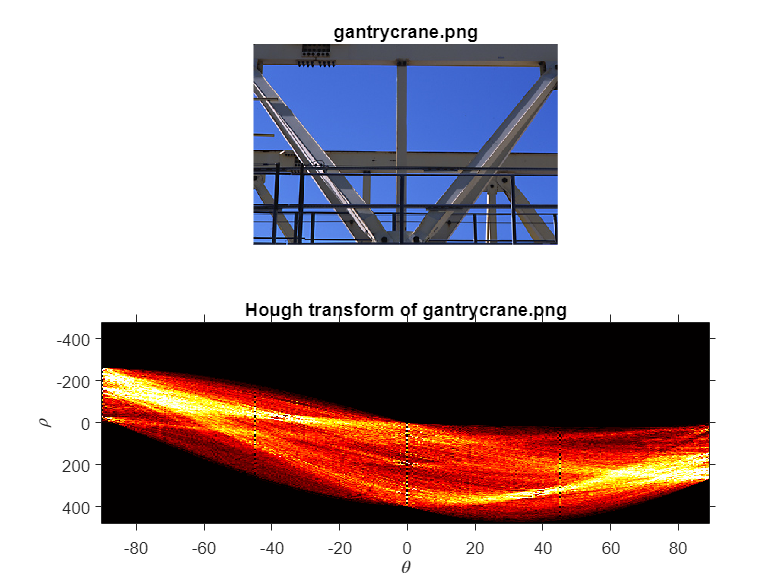

subplot(2,1,1);
imshow(RGB);
title('gantrycrane.png');
subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform of gantrycrane.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

*Copyright 2012 The MathWorks, Inc.*